# This routine is intended at analyzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do: 

- Add error bars

For dT data, use the percent temperature increase + standard deviation

For dCp values, add the SampHCErrmJmoleK field 

- Normalize with respect to molar mass

## Import data

Data = ImportCpDR('2018-07-31_TmVO4-LS5228-DR-HC180731.dat');

## Assign variable names and get rid of NaN rows

T = [Data.SampleTempKelvin];
Data(any(isnan(T), 2), :) = [];% Remove rows where T is NaN
H = [Data.FieldOersted];

## Separate data according to value of field

[uh,~,X] = unique(round(H));
split = accumarray(X,1:size(Data,1),[],@(r){Data(r,:)});
for i=1:length(split)
    split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
end

## Plot the full dataset

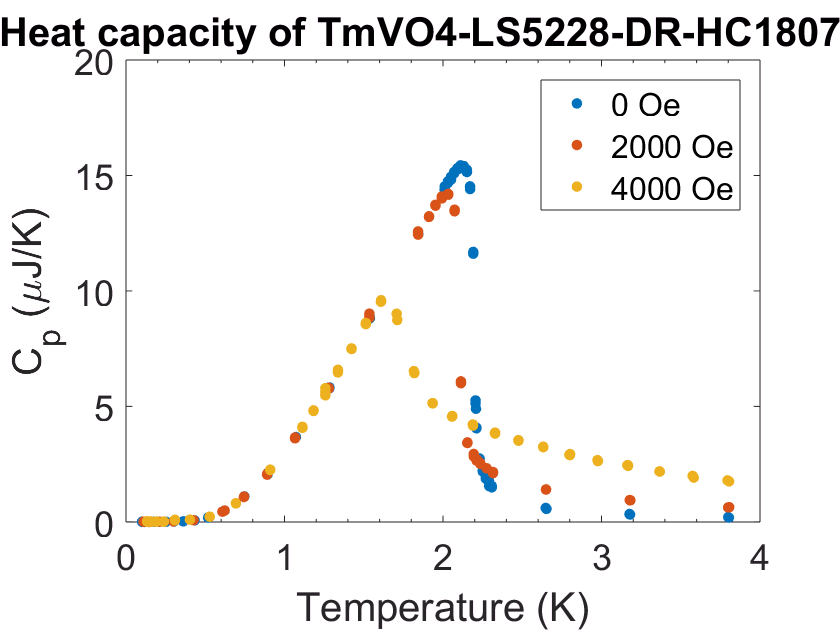

close 
figure
for i=1:length(split)
    plot(split{i}.T,split{i}.Cp,'.','MarkerSize',18,'DisplayName',[num2str(uh(i)),' Oe'])
    hold on
end
xlabel('Temperature (K)')
ylabel('C_p (\muJ/K)')
title('Heat capacity of TmVO4-LS5228-DR-HC180731')
legend('show')

## How to fit the data?

Since gamma depends on T self-consistently and Cp depends on both gamma and T, the only way to fit the data is to:

- Determine gamma numerically from T

- Fit Cp as a function of gamma and T

Edit 2018-10-03: the above suggestion does not work because Matlab can only take one argument for a 1D curve. Solution: since T is an analytical function of gamma (even though gamma is not an anlytical function of T), fit Cp as a function of gamma. Then, use the extracted fitting parameters to plot Cp vs T (not a fit though).

## Initialize data set to fit

clear T; clear Cp; clear dT
maxT = 2.1;% at 0T, for temperatures below maxT, heat capacity looks mean-field
T = split{1}.T(split{1}.T<maxT);% split{1} is the data at 0T
Cp = split{1}.Cp(split{1}.T<maxT);

## Determine gamma 

gamma = 0.2*ones(length(T),1);% initialize pseudospin array
% Tred = @(x,t) 2.2*2*x./atanh(2*x)-t;% Tred = T_calculated - T_measured
x0 = [10^-15 0.5];% range of the pseudospin
g = @(t) fzero(@(x) 2.2*2*x./atanh(2*x)-t,x0);% total pseudospin as a function of temperature t
% results from identifying the abscissa of the zero of 
% the anonymous function passed as argument of the fzero function

The expression of the anonymous function inside fzero is that of a reduced temperature defined as T_caluclated - T_measured, such that it takes the value zero when T_calculated = T_measured. This expression results from inverting the self-consistent equation 2*gamma = th(beta*gamma/2), where gamma is the total pseudospin and beta is the inverse temperature beta = 1/(k_B*T). Therefore, when the function takes the value zero, the correponding abscissa is the value of the total pseudospin at the measured temperature.

Note: the equation 2*gamma = th(beta*gamma/2) is for a reduced beta = beta/beta_c such that k_B*T_c/J_0 = 1/4. In order to get the actual value of the critical temperature, one needs to multiply k_B*T by 4*T_c. The factor 2 in the numerator of the function results from the multiplication by 4 and the factor 2.2 is the actual value of T_c (for this particular sample).

for j = 1:length(gamma)
%     t = T(j);
%     fun = @(x) Tred(x,t);
    gamma(j) = g(T(j));% fzero(fun,x0);
end

Note: to check the validity of the result, calculate T(gamma) for the calculated gamma, and take the difference with the original value of T. The result should be less than 1% off, ideally less than 1/1000. 

## Plot reduced temperature of the last data point as a function of gamma

Just to show what is going on in the above code

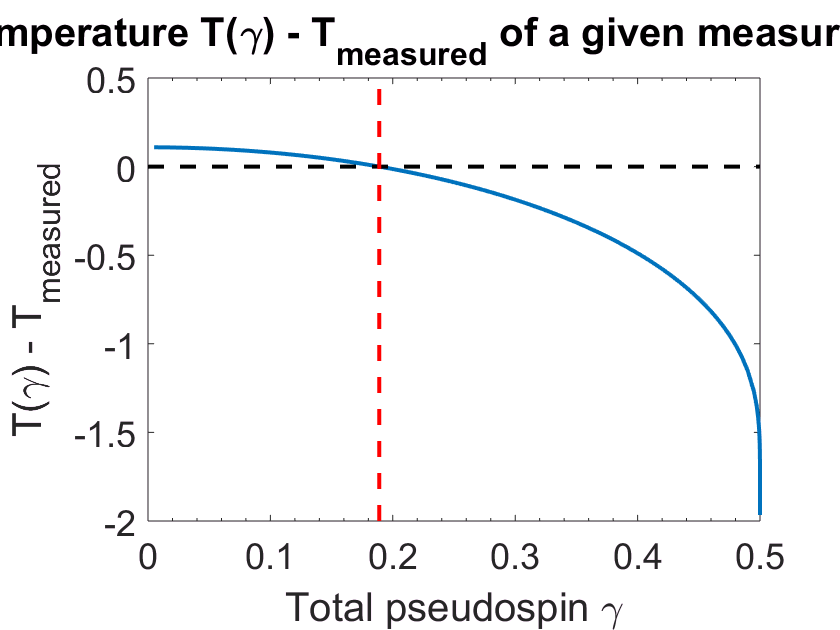

Tred = @(x) 2.2*2*x./atanh(2*x) - T(j);% Reduced temperature at temperature T(j)
% Tred is the same function as the anonymous function passed as argument of fzero
% in the definition of g, taken at a temperature T(j)
figure 
rev_x = [logspace(-15,-2),0.01:0.01:0.99];
x = 0.5.*(1-rev_x);% pseudospin values, with log scale close to Sz,max=0.5
plot(x,Tred(x))% plot Tred vs gamma; 
% the above code uses fzero to extract the value of gamma for which Tred = 0 
% i.e. T_calculated = T_measured
hold on
y = 0;
line(xlim,[y,y],'Color','black','LineStyle','--')% plot a horizontal line at y=0 
% and span it to the current figure's x limits
g0 = gamma(j);
line([g0,g0],ylim,'Color','red','LineStyle','--')% plot a vertical line at x=gamma(j)=g(T(j))
% and span it to the current figure's y limits
xlabel('Total pseudospin \gamma')
ylabel('T(\gamma) - T_{measured}')
title('Reduced temperature T(\gamma) - T_{measured} of a given measured temperature')

## Plot gamma

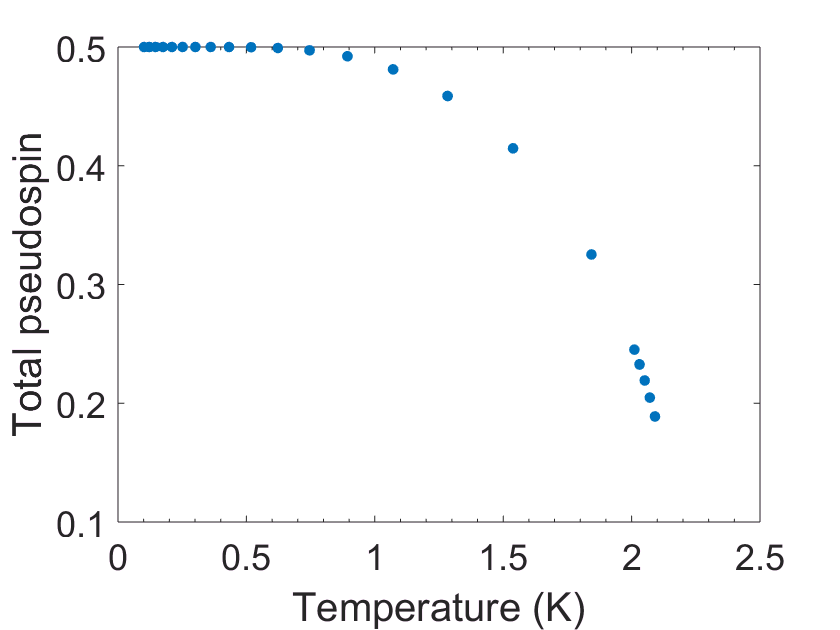

figure 
plot(T,gamma,'.')
xlabel('Temperature (K)')
ylabel('Total pseudospin')

## Fit the data at 0T

The expression of Cp(gamma) is:

a*(atanh(2*x))^2*(sech(atanh(2*x)))^2/(1-(sech(atanh(2*x)))^2*atanh(2*x)/(2*x))

or, since (sech(X))^2 = 1 - (tanh(X))^2:

a*(atanh(2*x))^2*(1-4*x^2)/(1-(1-4*x^2)*atanh(2*x)/(2*x))

where x = gamma

See function fitCpvsPseudospin.m

fitCp0T =      General model:
     fitCp0T(x) = A*(atanh(2*x))^2*(1-4*x^2)/(1-(1-4*x^2)*atanh(2*x)/(2*x))
     Coefficients (with 95% confidence bounds):
       A =       11.12  (11.1, 11.14)

gof0T = struct with fields:
           sse: 0.2444
       rsquare: 0.9999
           dfe: 65
    adjrsquare: 0.9999
          rmse: 0.0613


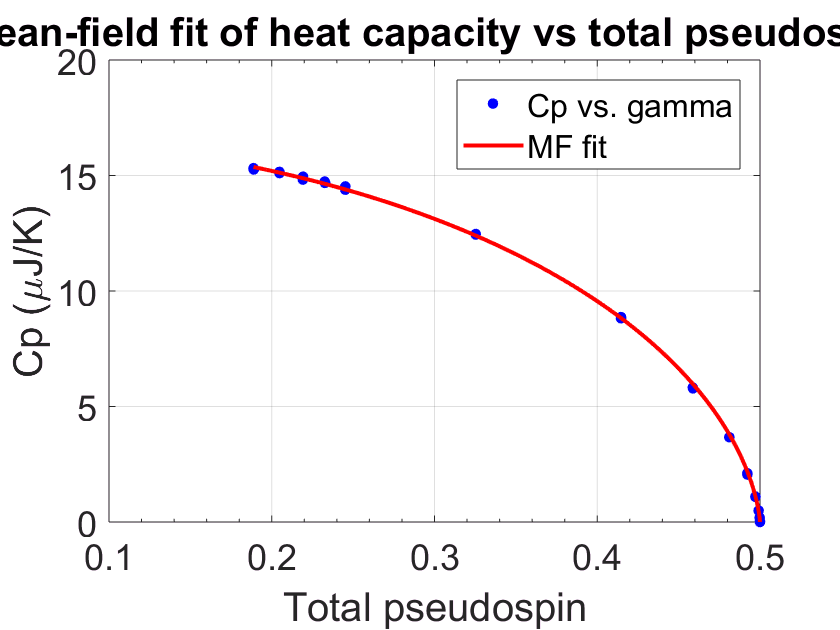

X = gamma./T;% the variable that appears in the expression of heat capacity is a ratio of pseudospin to temperature
[fitCp0T, gof0T] = fitCpvsPseudospin(gamma,Cp)

## Test the temperature scattering between data points supposedly taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutively at a given temperature. In order to check this, one can run the following code on the temperature variable T:

% nrep = 3% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
% Tsep = 4e-3% value of temperature separation to be tested, in Kelvin
% for i = 1:length(T)-nrep
%     if abs(T(i+nrep)-T(i)) < Tsep
%         T(i)
%     end
% end

If this piece of code outputs one or more values, that means that two different measurements were separated by less than Tsep. In this case, reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

Tm = [];
Cpm = [];
dCpm = [];
for i = 1:3:length(T)
ind = [i];
    for j = i+1:i+4
        if abs(T(j)-T(i))<0.004
            ind = [ind, j];
        end
        if j>= length(T)
            break
        end
    end
Tm = [Tm,mean(T(ind))];
Cpm = [Cpm,mean(Cp(ind))];
dCpm = [dCpm,std(Cp(ind))];
end

## Plot averaged data

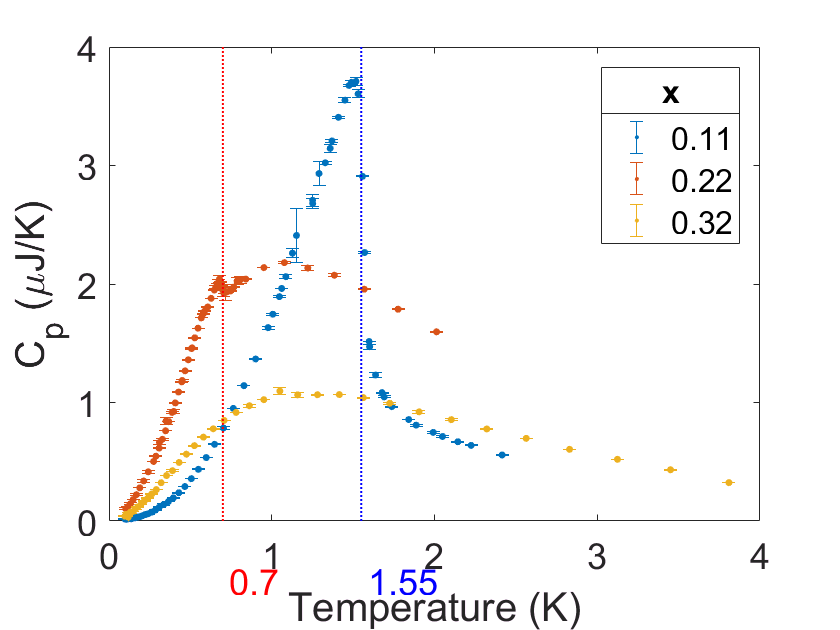

figure
hold on
cntr = 0;
Lm = round(L./3,0);
for i = Lm
    errorbar(Tm(cntr+1:cntr+i),Cpm(cntr+1:cntr+i),dCpm(cntr+1:cntr+i),'.','MarkerSize',12)
    cntr = cntr+i;
end
vline(1.55,'b:','1.55')
vline(0.7,'r:','0.7')
ylim([0 4])
xlabel('Temperature (K)')
ylabel('C_p (\muJ/K)')
hleg = legend('0.11','0.22','0.32');
title(hleg,'x')

% title('Heat capacity of Tm_{1-x}Y_xVO4')

## Fitting Schottky anomaly

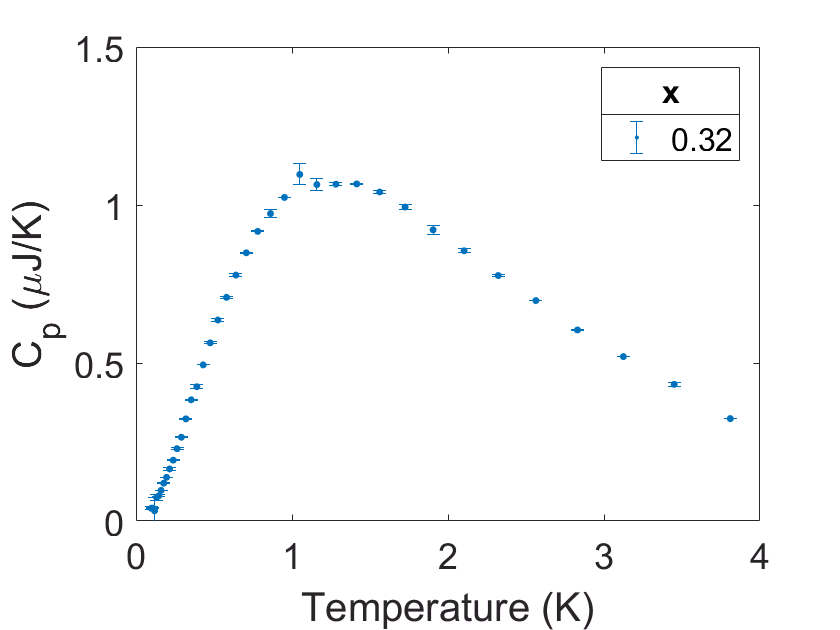

%% Separate the data of x=0.30 from the rest
figure
hold on
Tm30=Tm(Lm(1)+Lm(2)+1:end);
Cpm30=Cpm(Lm(1)+Lm(2)+1:end);
dCpm30=dCpm(Lm(1)+Lm(2)+1:end);
errorbar(Tm30,Cpm30,dCpm30,'.','MarkerSize',12)
ylim([0 1.5])
xlabel('Temperature (K)')
ylabel('C_p (\muJ/K)')
hleg = legend('0.32');
title(hleg,'x')

%% Fit: 'Schottky anomaly'.
[xData, yData] = prepareCurveData( Tm30, Cpm30 );


% Set up fittype and options.
ft = fittype( 'b*(a/x)^2.*sech(a/x)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.987660083686466 0.237061969477491];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );
MyCoeffs = coeffvalues(fitresult)

MyCoeffs =     2.2041    1.0932


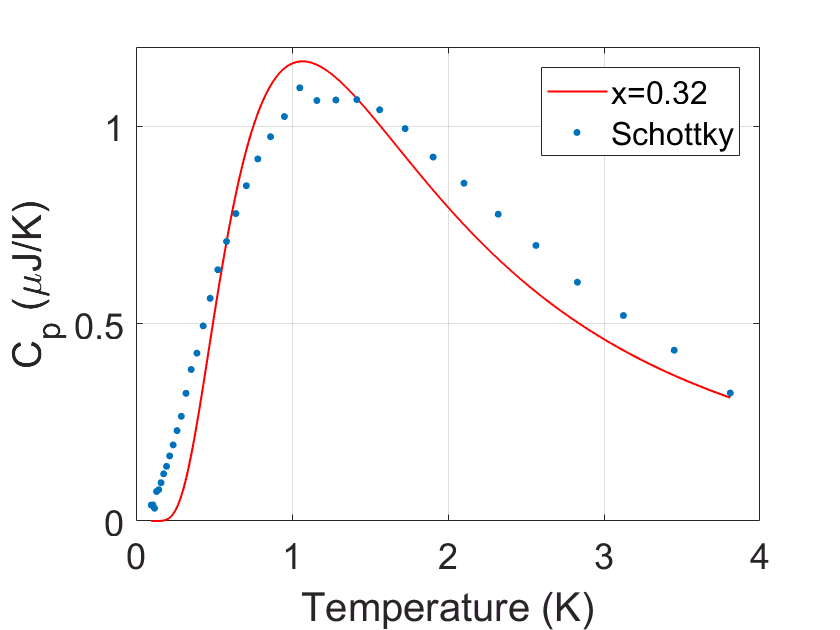


% Plot fit with data.
figure( 'Name', 'Schottky anomaly' );
plot(xData, yData,'.' , 'markers',12);
hold on
plot( fitresult)
legend('x=0.32', 'Schottky', 'Location', 'NorthEast' );
% Label axes
xlabel('Temperature (K)')
ylabel('C_p (\muJ/K)')
grid on